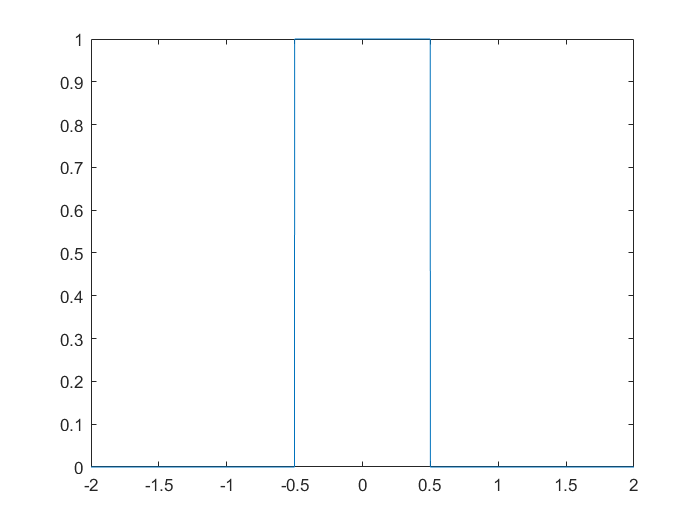

t1 =-2: 0.001: 2;
x1=ctstep(t1+0.5)-ctstep(t1-0.5);
x78=ones(1,length(t1))-x1;
figure
plot(t1,x1)

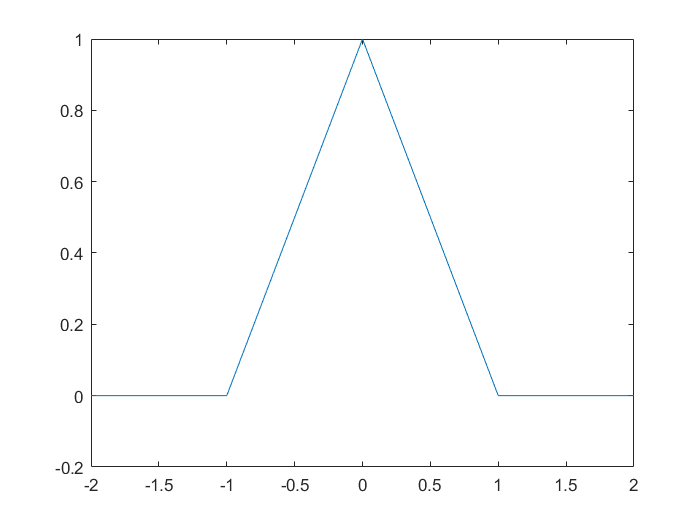

t2 =-2:0.001:2;
x2=ctramp(t2+1)-2*ctramp(t2)+ctramp(t2-1);
figure
plot(t2,x2)

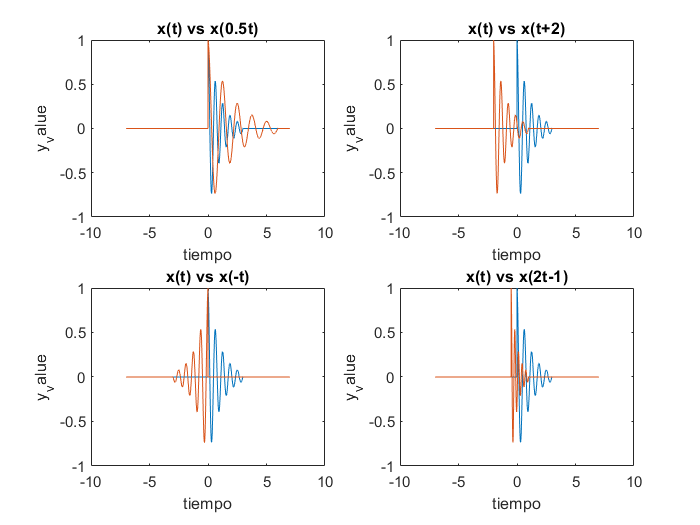

t3= -7:0.001:7;
x31=funcion3(t3);
figure

subplot(2,2,1)
x32=funcion3(0.5*t3);
plot(t3,x31,t3,x32)
title('x(t) vs x(0.5t)')
xlabel('tiempo')
ylabel('y_value')

subplot(2,2,2)
x33=funcion3(t3+2);
plot(t3,x31,t3,x33)
title('x(t) vs x(t+2)')
xlabel('tiempo')
ylabel('y_value')

subplot(2,2,3)
x34=funcion3(-t3);
plot(t3,x31,t3,x34)
title('x(t) vs x(-t)')
xlabel('tiempo')
ylabel('y_value')

subplot(2,2,4)
x35=funcion3(2*t3+1);
plot(t3,x31,t3,x35)
title('x(t) vs x(2t-1)')
xlabel('tiempo')
ylabel('y_value')

n1=-3:1:6;
x4=funcion4(n1);


n2=-13:1:13;
x51=funcion5(n2);
x52=funcion5(-n2-1);
x53=funcion5(3*n2);
x54=funcion5(zeros(size(n2)));
l=size(n2,2);

for i=1:1
    if ((mod(n2(i),2))==0)
        x54(i)=funcion5(n2(i)/2);
    end
end

function y3=funcion3(t3)
    y3=((exp(-t3)).*cos(10*t3)).*(ctstep(t3)-ctstep(t3-3));
end
function y4=funcion4(n)
    y4=dtimp(n+2)+ctstep(n)+ctramp(n-1)-2*ctramp(n-2)+ctramp(n-4);
end
function y5=funcion5(n)
    y5=(1.2.^n).*(ctstep(n+3)-ctstep(n-7));
end
